# Three Band Graphic EQ design and Simulink Controller

With hints for getting started provided by CPJ 19/4/2018

%  Three Band Graphic EQ design and Simulink Controller  (MB 3/26/2013)

clear 
close all

Fs=1050; % How should you chose this sampling frequency?

fc = [31.5, 63, 125, 250, 500, 1000, 2000, 4000, 8000, 16000];
Q = 0.707; % This is the value you need to find. 
% The value given is not necessarily the one that give the best solution!

f2 = fc*sqrt(1+1/(4*Q^2)) + fc/(2*Q)

f2 = 	1.0e+04 *

    0.0061    0.0122    0.0242    0.0483    0.0966    0.1932    0.3864    0.7728    1.5456    3.0912


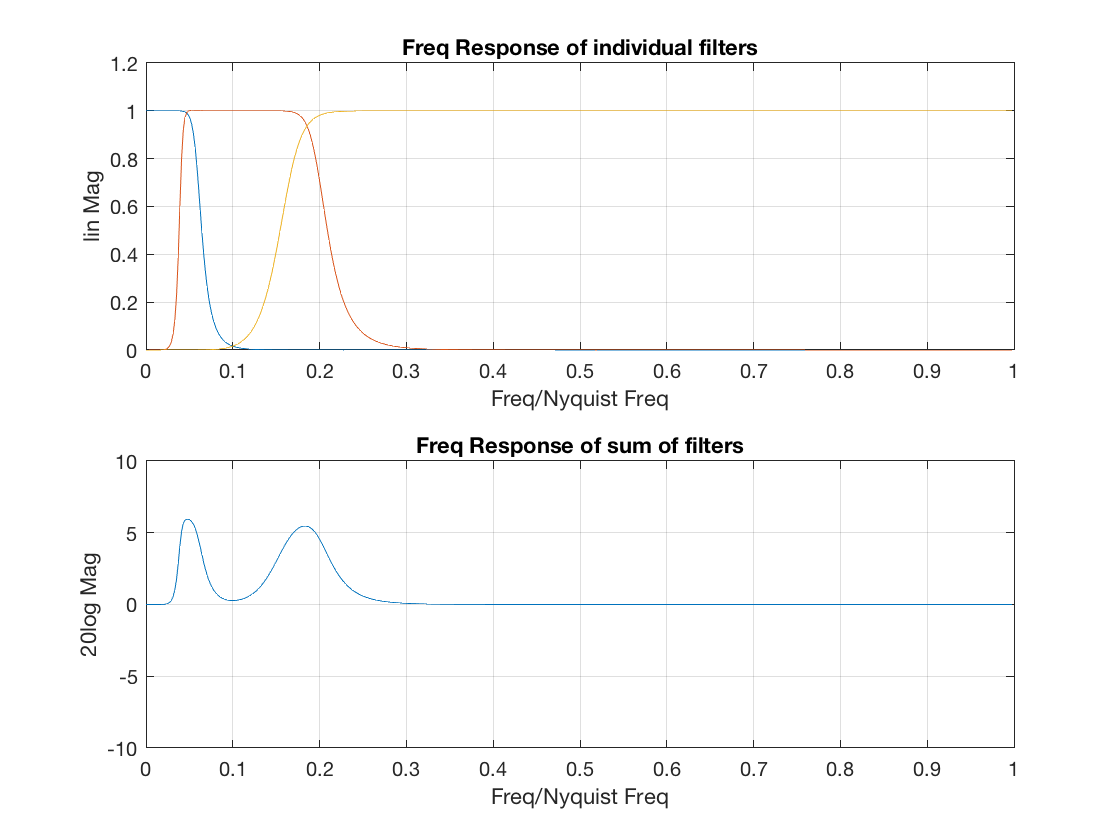


% what about f1?

% You need to compute the nyquist frequency fn which is half the sampling frequency

% Change these calls so that the cut-off frequencies are related to fc
% Hint f/fn gives the equivalent frequency
[B1,A1] = butter(8,0.06, 'low');
[B2,A2] = butter(8,[0.04 0.2]);
[B3,A3] = butter(8,0.165, 'high');

% Use vectors throughout!
% Convert all frequencies to their sampled-data equivalents!
% Finally, get the right Q value for the 3-band given before your generalize the solution
% to the 10-band case.
[H1,W1] = freqz(B1,A1,512);
[H2,W2] = freqz(B2,A2,512);
[H3,W3] = freqz(B3,A3,512);

subplot(211)
plot(W1/pi, abs(H1), W2/pi,abs(H2), W3/pi,abs(H3))
grid on
title('Freq Response of individual filters')
xlabel('Freq/Nyquist Freq')
ylabel('lin Mag')

absH = abs(H1)+abs(H2)+abs(H3);

%absH = 2*abs(H1)+2*abs(H2)+1.4*abs(H3);

subplot(212)
plot(W1/pi, 20*log10(absH))
axis([0 1 -10 10])
grid on
title('Freq Response of sum of filters')
xlabel('Freq/Nyquist Freq')
ylabel('20log Mag')


% Try plotting these graphs on log-lin graph paper 
help semilogx